# Examen RA3L - Matlab Partie 2 - Janvier 2025

% Nom :    adda                                         /10
% Prénom : sab
% Matricule : 23027

Le fichier NewFile3.csv contient les données de tension U et de courant I (sur 12 périodes complète pour les 2 signaux), grandeurs d'une charge inductive compensée par une charge capacitive. L'ensemble de la charge est alimenté en tension alternative, qui oscille à 50 Hz. Le fait de compenser la charge inductive introduit une harmonique de rang 9 dans le signal de courant.

**1) **Les données csv (et non .mat !!) sont déjà chargées via les lignes de code implémentées ci-dessous. **Déterminer la fréquence (Fs) et la période d'échantillonage (Ts) afin de reconstruire le vecteur temporel. Visualiser ensuite la tension U et le courant I en fonction du temps. ***( /1 point)*

clear all
close all

% Début des lignes de code déjà présentes pour charger le ficher CSV
M=readtable("NewFile3.csv");
M=M{:,varfun(@isnumeric,M,'OutputFormat','uniform')};
U=M(:,1);
I=M(:,2);
clear M
% Fin des lignes de code déjà présentes pour charger le ficher CSV

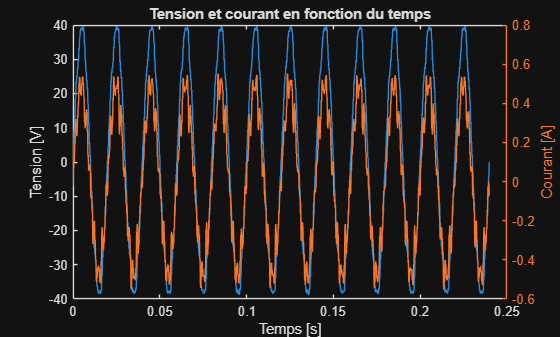

%code
%maxu=max(U);
%a=find(U==maxu);
a=length(U)/12;%Nombre d'échantillons par période =Nbre de points/ Nbre periode
%b=find(U==U(1)); MARCHE PAS TOUJOURS CAR ECHANTILLONAGE PAS forcement
%comme ca, je peux avoir 2X le meme points dans mon échantillonage comme je
%peux ne pas l'avoir
%c=(b(2)-b(1)); %NOmbre de points(échantillons) dans une période ou deux,
%on sait pas
T=1/50;
Ts=T/a;
fs=1/Ts;
n=0:1:length(U)-1;
t=n*Ts;
clf;
plot(t,U)
title('Tension et courant en fonction du temps')
xlabel('Temps [s]')
yyaxis left
ylabel('Tension [V]')
yyaxis right
plot(t,I)
ylim([-0.6 0.8])
ylabel('Courant [A]')

Résultat attendu :

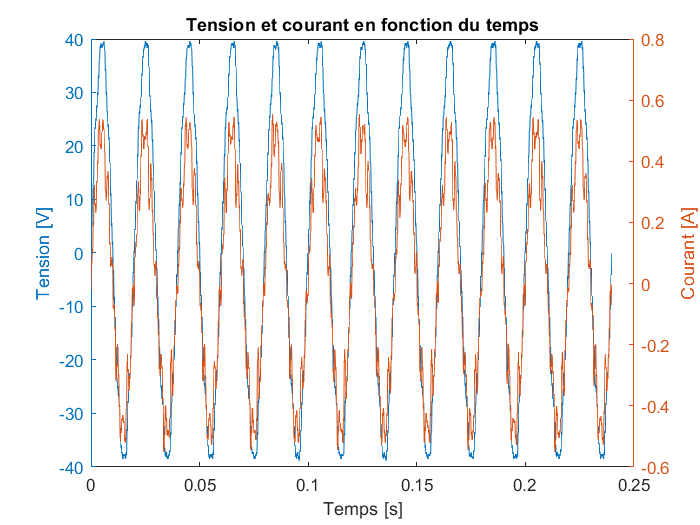

**2) Implémenter le code permettant d'appliquer la FFT sur le signal de courant** **en justifiant chaque étape ****sur feuille annexe****.*** ( /2.5 points)*

NB : Sans justification sur papier, le code ne rapportera aucun point. 

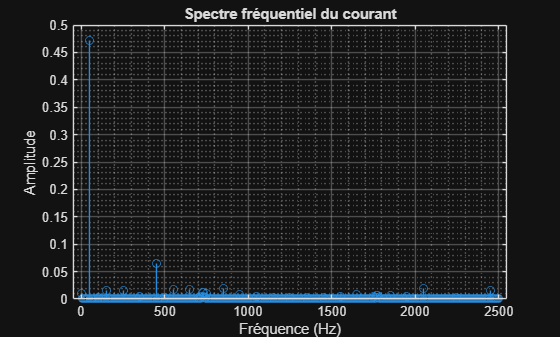

%code
N=length(I); %c'est le nombre d'échantillon
amp=abs(fft(I))/N; %héritage du dft inverse le 1/N , et on fait abs parce que c'est un nbre complexe et je veux que les amplitudes et fft c'est un algo pour fr dft
amp=amp(1:N/2+1); %parce que elle est symetrique donc on a 2 fois la meme amplitude mais déphasé donc au lieu de dessiner 2 fois la meme je le dessine en 1 fois en additionnant les amplitudes car on s'interesse pas a la phase
amp=amp.*2; %vu qu'on prend que la moitié du signal faut multiplié par 2 car il nous manque l'autre partie qui est identique
amp(1)=amp(1)/2; %la composante dc, 0hz n'a pas d'homologue du a la symétrie, elle n'est pas dédoublé donc quand on a tout multiplié par 2 faut rediviser Ohz par 2
n=0:1:N/2; %mon axe X commence à 0Hz donc pour que n(1)*df vaut 0hz faut que n vaut 0 donc on decale N vers la gauche de 1 

df=fs/N;  %FFT nous donne des données fréquentielles et ces données sont reparties sur la fréquence max possible qui est celle de fs ici 
f=n*df; %c'est mon axe X c'est les differentes frequences
clf;
stem(f,amp); % ca permet d'afficher nos valeurs sous formes de stem/batonnets, on a les amplitudes a differentes frequences
title('Spectre fréquentiel du courant')
xlabel('Fréquence (Hz)')
ylabel('Amplitude')
grid minor
grid on

Résultat attendu : 

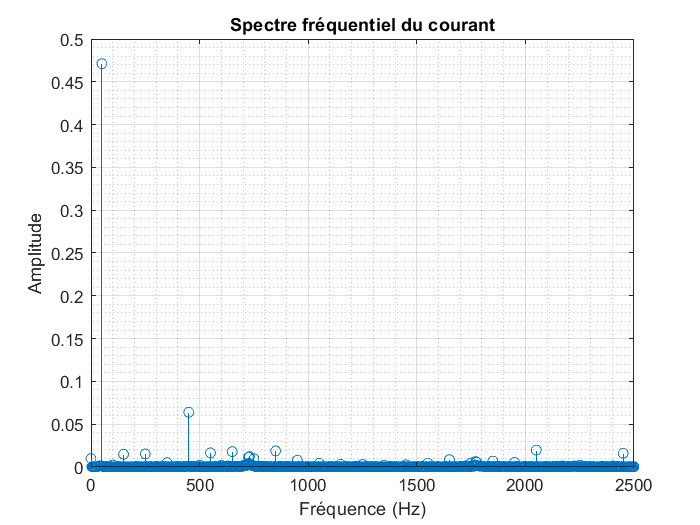

**3) Appliquer un filtre passe-bas, caractérisisé mathématiquement par la fonction de transfert H(s) (ci-dessous), au signal de courant I dont la fréquence de coupure **$\omega_{c\;}$** permet de réduire les fréquences supérieures à 500 Hz (**$\omega_{c\;} =2\pi *500$** rad/s) avec un coefficient d'amortissement **$\xi$ à 0.8 ($\left.\xi =0\ldotp 8\right)$**. **


$$H\left(s\right)=\frac{1}{\left(\frac{s^2 }{\omega_c^2 \;}+\frac{2s\xi }{\omega {\;}_c }+1\right)}$$


**Afficher le signal de sortie **(à stocker dans la variable Y)** et le signal d'entrée de ce filtre sur le même graphique. ***( /1 points)*

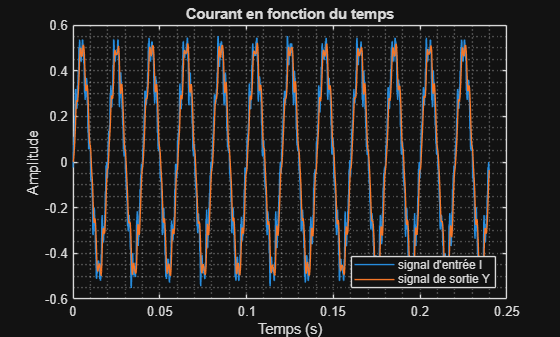

%code
xi=0.8;
wc=2*pi*500;
s=tf('s');
H=1/((s^2/wc^2)+(2*s*xi/wc)+1);
clf;
y=lsim(H,I,t);
plot(t,I,t,y)
title('Courant en fonction du temps')
ylabel('Amplitude')
xlabel('Temps (s)')
legend(("signal d'entrée I"),('signal de sortie Y'),'Location','southeast')
grid minor

Résultat attendu :

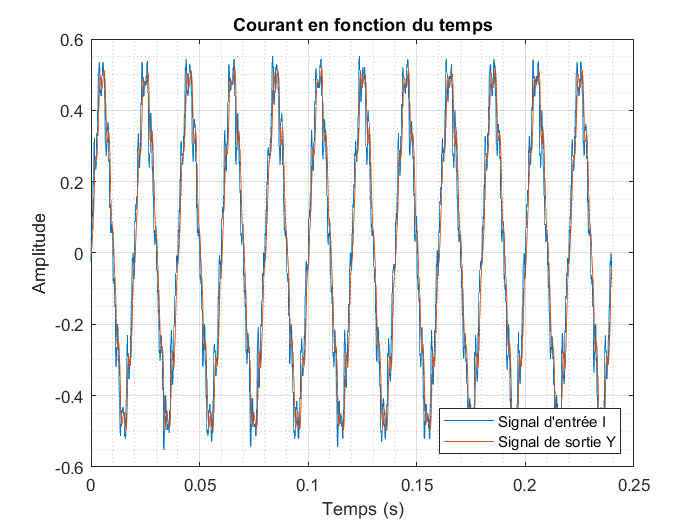

**4) Implémenter à nouveau le code permettant d'appliquer la FFT sur le signal de courant en sortie de filtre ****en travaillant avec une résolution fréquentielle de 25 Hz****. ***( /0.5 points)*

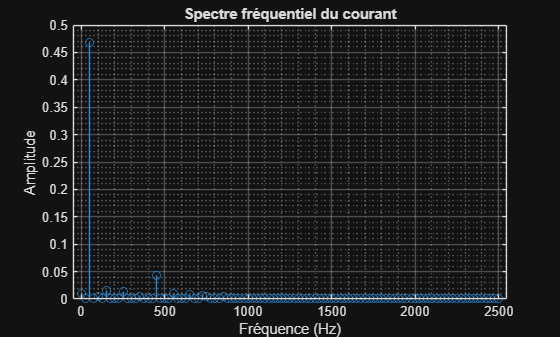

%code
dF1=25; %c'est ce qu'on impose
N1=fs/dF1;% ca donne un chiffre rond mais c'est pas toujours le cas si c'est pas rond tu utilises floor ou ceil, on calcule le nombre de point je dois prendre si je veux changer la resolution
y1=y(1:N1);% je prends que les points qui m'interesse car nouvelle resolution
amp1=abs(fft(y1))/N1; %fft 
amp1=amp1(1:N1/2+1); 
amp1=amp1.*2;
amp1(1)=amp1(1)/2;
n=0:1:N1/2; 
 
f1=n*dF1; 
clf;
stem(f1,amp1); % ca permet d'afficher nos valeurs sous formes de stem/batonnets, on a les amplitudes a differentes frequences
title('Spectre fréquentiel du courant')
xlabel('Fréquence (Hz)')
ylabel('Amplitude')
grid minor
grid on

Résultat attendu : 

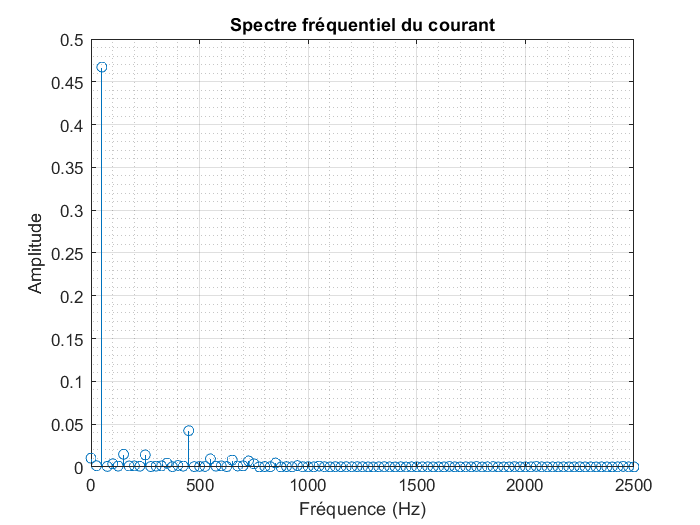

**5) Comment interpréter les résultats obtenus aux questions 2 et 4 sachant que les amplitudes inférieures à 0.05 ne sont pas pertinentes ? Justifier, ****sur feuille annexe****, avec du texte et/ou avec un/des schémas. ***( /2.5 points)*

Bah on a la meme juste on a beaucoup moins de données fréquentiel car on fait des pas beaucoups plus grand donc je vois pas ce qu'il se passe entre les pas contrairement à avant et aussi on voit que y'a des frequences ou on a perdu les infos et en plus on a filtré donc les frequences au dessus de 500hz sont fortement filtres et celles autour de 500hz sont un peu filtré et les frequences beaucoup plus petites que 500 ne sont pas filtres du tout

**6) Afficher le diagramme de bode du filtre passe-bas, ainsi que les fréquences pour lesquelles le système a été sollicité.**

**Vérifier que le gain obtenu via le diagramme de bode est proche de celui obtenu via l'analyse fréquentielle des signaux en entrée et en sortie du filtre. ***( /1.5 points)*

%code
w=[50 450]*2*pi

w = 1.0e+03 *

    0.3142    2.8274


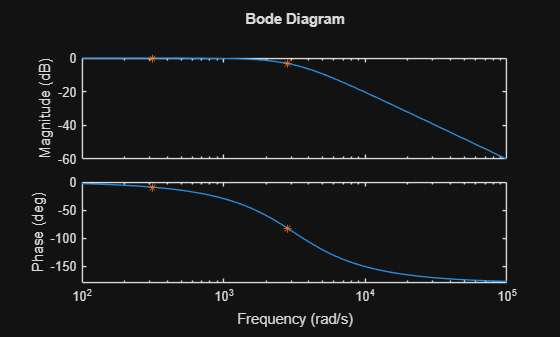

clf;

bode(H)
hold on
bode(H,w,"*")

[mag50decimal]=bode(H,w(1))

mag50decimal = 0.9972

[mag450decimal]=bode(H,w((2)))

mag450decimal = 0.6885


%mag50dB=20*log10(mag50decimal)
%mag450dB=20*log10(mag450decimal)
i50=50/df+1;
i450=450/df+1;
ampI50sansfiltre=amp(round(i50));
ampI450sansfiltre=amp(round(i450));
ampI50=amp1(3); %amplitude à 50hz dans le fft et i=3 car i=1 f=0 i=2 f=25 FILTRE
ampI450=amp1(19); %filtrE
mag50fft=ampI50/ampI50sansfiltre;
mag450fft=ampI450/ampI450sansfiltre;
Gain_bode=[mag50decimal mag450decimal]

Gain_bode =     0.9972    0.6885


Gain_fft=[mag50fft mag450fft]

Gain_fft =     0.9916    0.6640


Résultat attendu :

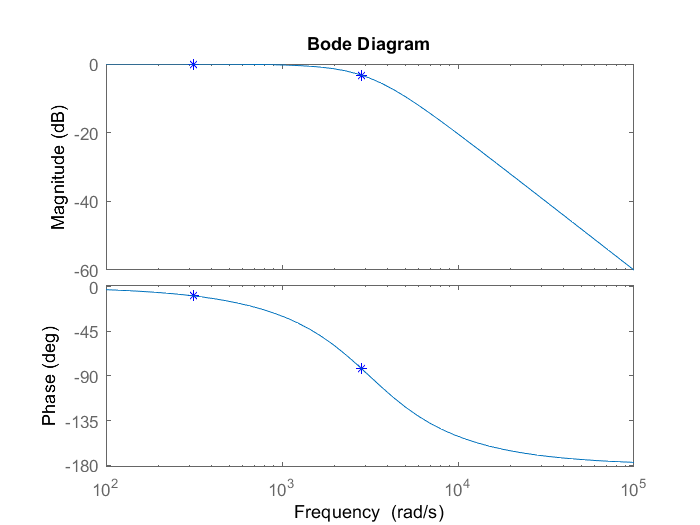

**7) ****Sur feuille annexe****, expliquer pourquoi il y a un décalage temporel entre l'entrée et la sortie du filtre sur base des résultats obtenus aux questions 3 et 6. ***( /1 points)*

NB : il est conseillé d'utiliser Matlab pour vous aider à répondre à cette question sur papier. 

%code

parce qu'il y'a un déphasage